# Homework 3 - GEOPH 522

Isabella Welk 1 Oct 24

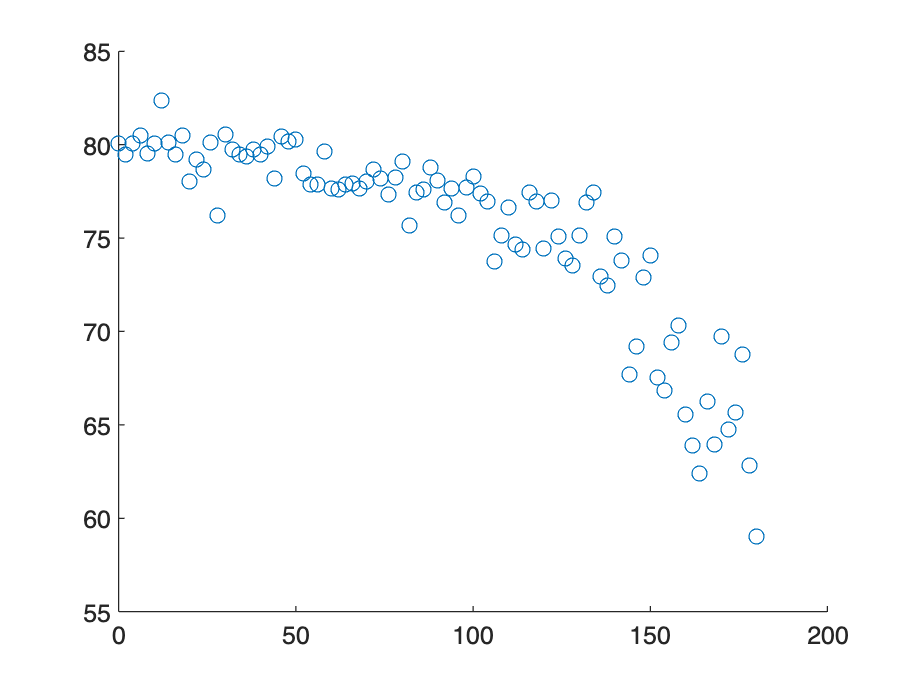

D = load("icevelocity.txt");

z = D(:,1);
v = D(:,2);

figure(1);clf
scatter(z,v,'o')

degree = [0 1 2 3 4];

figure(1); hold on

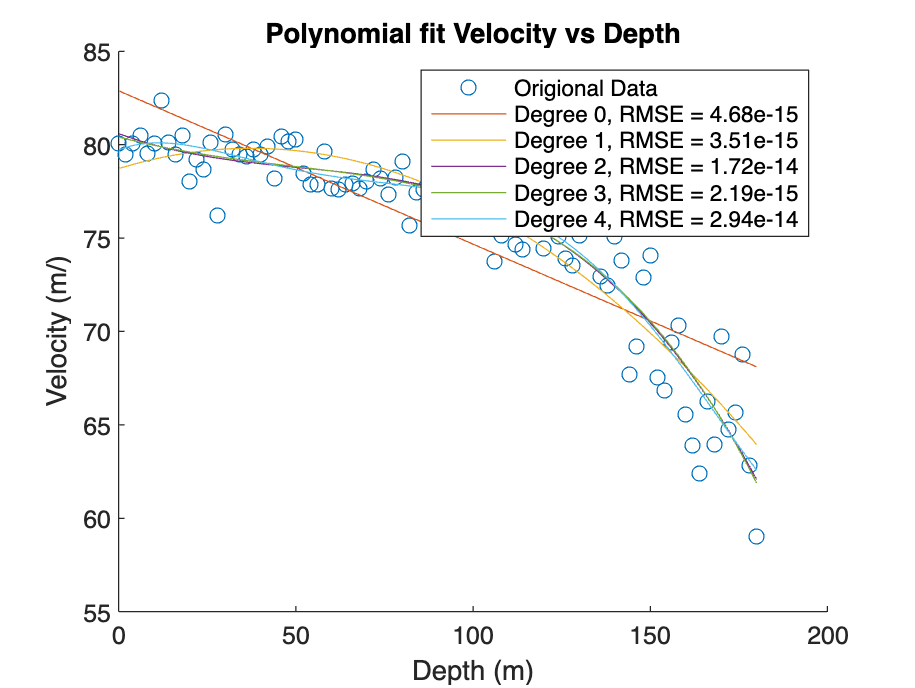

for n = 1:length(degree)
    P = polyfit(z,v,n); % fit the model
    vmod(:,n) = polyval(P,z); % evaluate the model
    RMSE(n) = sqrt((mean(vmod(:,n)-v).^2)); % model accuracy
   
end

figure(1); clf
scatter(z,v,'o','DisplayName','Origional Data'); hold on

for n = 1:length(degree)
    plot(z,vmod(:,n),'DisplayName',sprintf('Degree %d, RMSE = %.2d', degree(n), RMSE(:,n)));
end


title('Polynomial fit Velocity vs Depth')
xlabel('Depth (m)')
ylabel('Velocity (m/)')
legend('show')
hold off

pTrain = 0.9; % use 90% for training
P = zeros(1000,2); % intitialize P
for n = 1:1000
    [trainset, testset] = getTrainTest(D,pTrain);
    ztrain = trainset(:,1);
    v_train = trainset(:,2);

    P(n,:) = polyfit(ztrain, v_train,1);
    ztest = testset(:,1);
    v_test = testset(:,2);

    vmodel = polyval(P(n,:),ztest);
    rmsCSV(n) = sqrt(mean((vmodel-v_test).^2));
end

muP = mean(P);
sigP = std(P);

results = table(muP',sigP','VariableNames',{'Mean','Standard Deviation'}, ...
    'RowNames',{'Slope','Intercept'});
disp(results);

                   Mean       Standard Deviation
                 _________    __________________

    Slope        -0.082271        0.0072101     
    Intercept       82.908          0.52797     



Cross validation

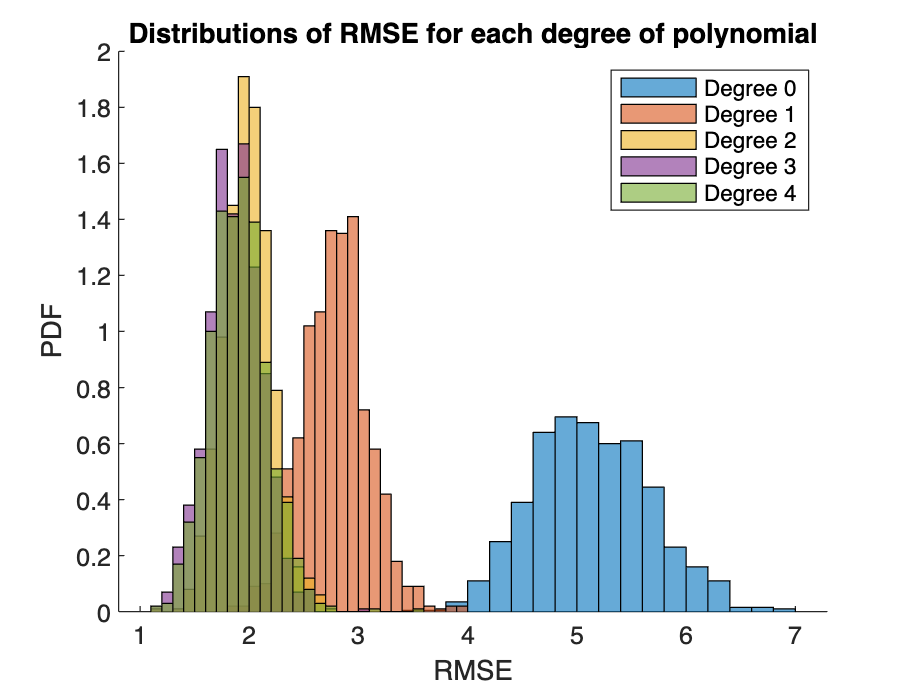

pTrain = 0.9; % use 90% for training
P = zeros(1000,5); % intitialize P
for n = 1:1000
    [trainset, testset] = getTrainTest(D,pTrain);
    ztrain3 = trainset(:,1);
    vtrain2 = trainset(:,2);
    z_test = testset(:,1);
    vtest2 = testset(:,2);

    for d = 1:length(degree)
        P2 = polyfit(ztrain3, vtrain2,degree(d));
        vmodel2 = polyval(P2,z_test);
        rmsCSV2(n,d) = sqrt(mean((vmodel2-vtest2).^2));
    end
end

figure(2);clf
hold on
for i = 1:length(degree)
        histogram(rmsCSV2(:,i), 'Normalization','PDF','DisplayName', ...
            sprintf('Degree %d', degree(i)));
end
title('Distributions of RMSE for each degree of polynomial');
xlabel('RMSE');
ylabel('PDF');
legend('show')
hold off

## Moving window

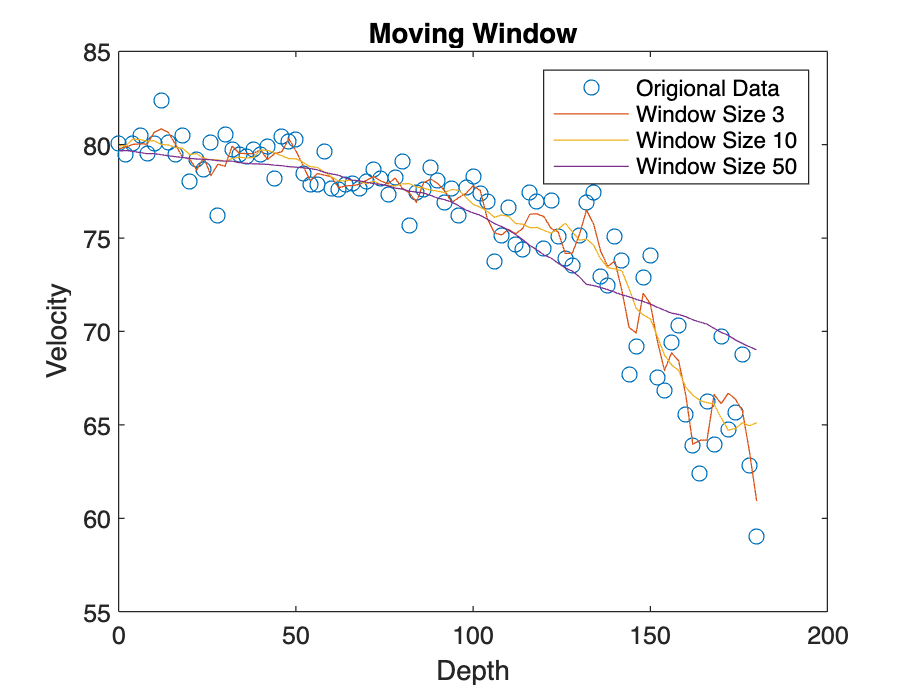

winsize = [3, 10, 50];
figure(3);clf
plot(z,v,'o','DisplayName','Origional Data'); hold on
for i = 1:length(winsize)
    plot(z,movmean(v,winsize(i)),'DisplayName',sprintf('Window Size %d', winsize(i)))% using the movmean() function to calculate the moving window
end
legend('show')
title('Moving Window')
xlabel('Depth')
ylabel('Velocity')
hold off

weighted moving window

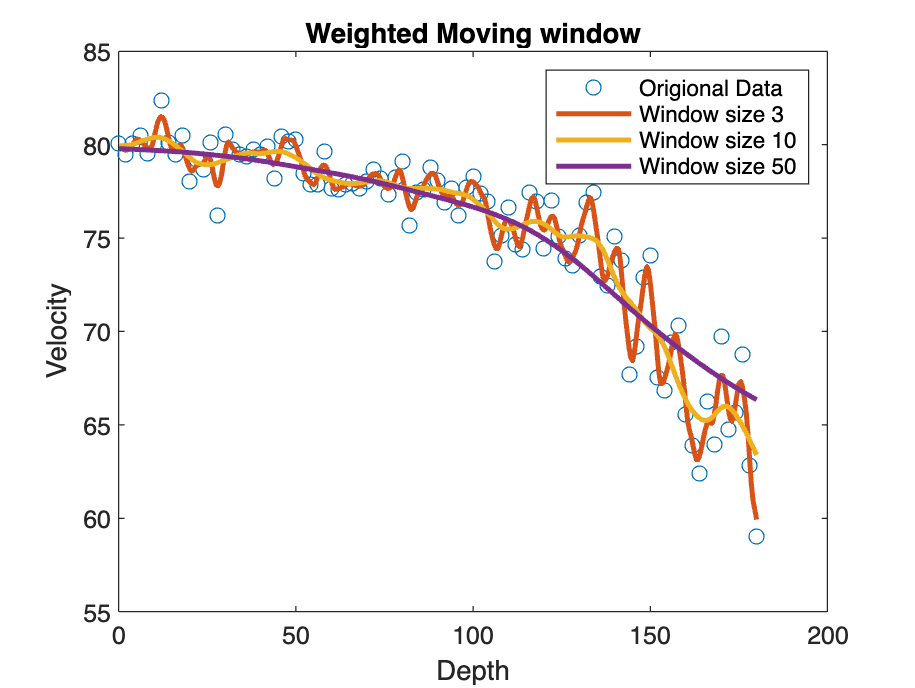

figure(4); clf
plot(z,v,'o','DisplayName', 'Origional Data');

zmod = 0:0.5:180;
vmod = zeros(length(zmod), length(winsize));
for i = 1:length(winsize)
    vmod(:,i) = nonparametric_smooth(z,v,zmod,winsize(i));
end

hold on
for i = 1:length(winsize)
    plot(zmod, vmod(:,i),'LineWidth',2,'DisplayName',sprintf('Window size %d', winsize(i)))
end

title('Weighted Moving window')
xlabel('Depth')
ylabel('Velocity')
legend('show')
hold off

finding optimum window size 

pTrain = 0.9; % use 90% for training
[trainset3, testset3] = getTrainTest(D,pTrain);
z_train = trainset3(:,1);
v_train = trainset3(:,2);
z_test = testset3(:,1);
v_test = testset3(:,2);

for i = 1:length(winsize) % cacluating moving window size and rmse
    vmod2 = nonparametric_smooth(z_train,v_train,zmod,winsize(i));
    v_m = interp1(zmod,vmod2,z_test,"linear","extrap"); % interpolating so rmse for matching points
    rmse(i) = sqrt(mean((v_m-v_test).^2));
end

[~,best] = min(rmse);
fprintf('The optimum window size is %d.',winsize(best));

The optimum window size is 50.

## ice velocity

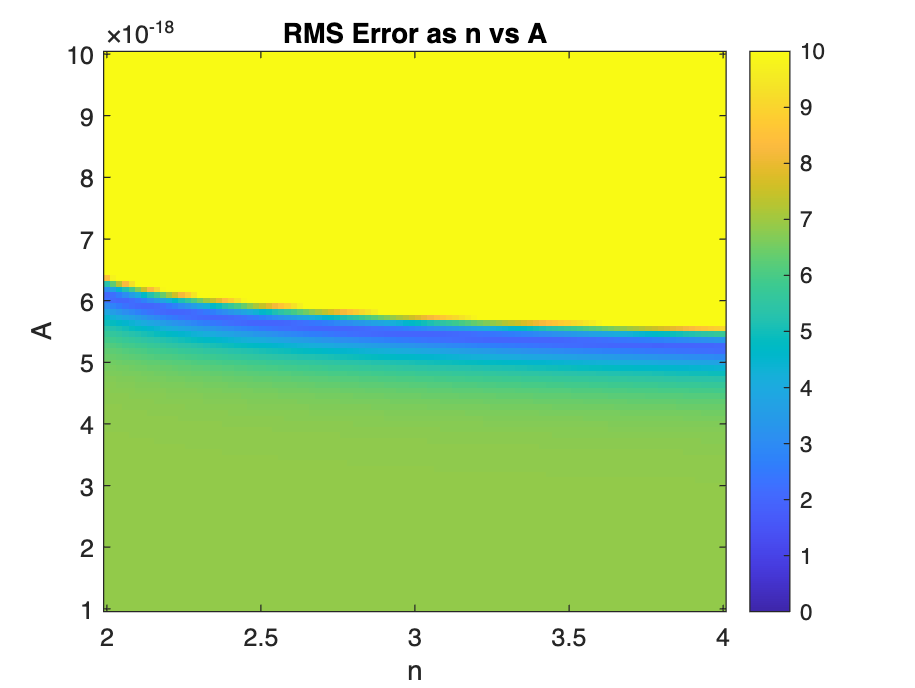

v0 = v(1);
rho = 917; %kg/m3
g = 9.8; % m/s2
theta = 10;
theta = deg2rad(10);

A_range = linspace(1e-18,10e-18,100);
n_range = linspace(2,4,100);
RMS = zeros(length(A_range),length(n_range));

for i = 1:length(n_range)
    for j = 1:length(A_range)
        
        V_mod = velocity(A_range(j), n_range(i),v0,z);
        RMS(j,i) = sqrt(mean((V_mod-v).^2));
    end
end 

% plot(,A)
figure(5); clf
imagesc(n_range,A_range,RMS');
set(gca,"YDir",'normal')
caxis([0 10])
colorbar;
title('RMS Error as n vs A')
xlabel('n');
ylabel('A');

## gradient search

finding optimum A and n values using fminsearch()

% preform optimization 
initial_guess = [2e8,3]; % starting point for search

%options = optimset('MaxFunEvals',2000); % I recieved an error that the max number of evaluations was exceeded so limited it
funct = @(params) vel_rmse(params(1),params(2),v,z,v0);
best = fminsearch(funct, initial_guess); 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 3.407270 




fprintf('The best parameters are A= %f and n= %f\n', best(1), best(2));

The best parameters are A= 0.998371 and n= -0.237134



% tried a second time
initial_guess = 2e8;
n = 3;

options = optimset('Display', 'iter');
pbest = fminsearch(@rmse2, initial_guess, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1              NaN         
     1            2              NaN         initial simplex
     2            5              NaN         shrink
     3            8              NaN         shrink
     4           11              NaN         shrink
     5           14              NaN         shrink
     6           17              NaN         shrink
     7           20              NaN         shrink
     8           23              NaN         shrink
     9           26              NaN         shrink
    10           29              NaN         shrink
    11           32              NaN         shrink
    12           35              NaN         shrink
    13           38              NaN         shrink
    14           41              NaN         shrink
    15           44              NaN         shrink
    16           47              NaN         shrink
    17           50              NaN         shrink
    

A = pbest/((rho*g*sin(theta))^2);
fprintf('The best parameter A = %.6e\n', A);

The best parameter A = 8.212941e+01


## monte carlo

mc = 1000;

pTrain = 0.9; % use 90% for training
[train4, test4] = getTrainTest(D,pTrain);
z_train = train4(:,1);
v_train = train4(:,2);

z_test = test4(:,1);
v_test = test4(:,2);

opt_A = zeros(mc,1);
rms = zeros(mc,1);

% using same in initial guess as above initial_guess
for i = 1:mc
   options = optimset('Display', 'iter');
   pbest = fminsearch(@rmse_train, initial_guess, options);
   opt_A(i) = pbest/((rho*g*sin(theta))^2);
   rms(i) = rmse_train(opt_A);
end

 
 Iteration   Func-count         f(x)         Procedure
     0            1              NaN         
     1            2              NaN         initial simplex
     2            5              NaN         shrink
     3            8              NaN         shrink
     4           11              NaN         shrink
     5           14              NaN         shrink
     6           17              NaN         shrink
     7           20              NaN         shrink
     8           23              NaN         shrink
     9           26              NaN         shrink
    10           29              NaN         shrink
    11           32              NaN         shrink
    12           35              NaN         shrink
    13           38              NaN         shrink
    14           41              NaN         shrink
    15           44              NaN         shrink
    16           47              NaN         shrink
    17           50              NaN         shrink
    

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in rmse_train (line 6)
    vmodel = 80.0867 - (A * z_train.^(n + 1));

Related documentation



figure(6); clf
histogram(rms,'BinCounts',20);
figure(7); clf
histogram(opt_A,'BinCounts',20);

mu_optA = mean(opt_A);
sig_optA = std(opt_A);

figure(5); clf
imagesc(n_range,A_range,RMS');
set(gca,"YDir",'normal')
caxis([0 10])
colorbar;
title('RMS Error as n vs A')
xlabel('n');
ylabel('A');
hold on
plot(n,mu_optA)
errorbar(opt_A,sig_optA,'o','MarkerSize',2,'LineWidth',2)

mu_rmse = mean(rms);
sig_rmse = std(rms);

simA = normrnd(mu_optA,sig_optA,[1000,1]);
simRMS = normrnd(mu_rmse,sig_rmse,[1000,1]);

## kstest

kstest(A)

ans = logical
   1


kstest(rms)

ans = logical
   1


## Code from class

%Brute Force
% ns = length(v); % numebr of data points
% A0 = 20:1:150 % range of A0
% A1 = -1:0.005:0.505 % range A1
% 
% rmse = zeros((length(A0),length(A1))); % initializes array
% 
% for n = 1:range(length(A0)) % 1 less than length of A0
%     for n2 = range(length(A1))
%         vmodel = A0(n)+A1(n2)*z % linear model
%         rmse(n,n2) =  sqrt(mean((vmodel-v).^2))
%     end
% end

% % plot as a heat map
% % % translate to matlab syntax from previous examples
% figure(2); clf
% plot(rmse,extent=[A1.min(), A1.max(),A0.min(),A0.max()], aspect = 'auto', ...
%     origin = 'lower', cmap='viridis',vmin=0,vmax=20)
% xlabel('A1')
% ylabel('A0')
% colorbar(label='RMSE')
% title('RMSE values for lineral model')
% hold on
% plot(P(1),P(2),'ro')
% 

% Gradient Descent
% % nedler mean sintex approach
% 
% % define the objective/ cost function 
% 
% function [rmse] = RMSEval(P)
%  vmodel = P(1)*z+P(1)
%  rmse =  sqrt(mean((vmodel-v).^2)) 
% end
% 
% % preform optimization 
% initial_guess = (-1,20); % starting point for search
% result = minimize(RMSEval,initial_guess) %% this is python syntax
% pbest = result
% fprintf(f'best parameters: slope:{pbest(1)}, intercept = {pbest(2)})
% 
% 
% % plot as a heat map
% % % translate to matlab syntax from previous examples
% figure(2); clf
% plot(rmse,extent=[A1.min(), A1.max(),A0.min(),A0.max()], aspect = 'auto', ...
%     origin = 'lower', cmap='viridis',vmin=0,vmax=20)
% xlabel('A1')
% ylabel('A0')
% colorbar(label='RMSE')
% title('RMSE values for lineral model')
% hold on
% plot(P(1),P(2),'ro')
% hold on
% plot(pbest(1),pbest(2), 'kx')
% 
% %% compare to analytic solution
% zsum = sum(z);
% z2sum = sum(z^2)
% M = array([zsum,len(z)],[z2sum,zsum])
% vsum = sum(v);
% vzsum = sum(z*v);
% y = array([vsum,vzsum])
% pbest2 = linalg.slve(M,y)
% fprintf()
% figure(2); hold on
% plot(pbest2(1),pbest2(2),'*')